# **Lab 8: Face recognition using LDAs**

In this lab, we will employ LDA and SVM to identify the faces from different people.

We will use the ORL database, available on AT&T’s web site, as in previous labs. This database contains photographs showing the faces of 40 people (s1, s2, . . . , s40). Each one of them was photographed 10 times. These photos are stored as images in levels of grey with 112x92 pixels. The data has been split in two parts: train and test. For each person, we use the first 9 photographs for training and the last photograph for test. 

1. Load the training and the testing data (separately) and change each d1xd2 (112x92)  photograph into a vector; 

%% 1. Load the training data 
% d1xd2 = 112x92
pathTrain = 'orl_faces/Train/';
pathTest =  'orl_faces/Test/';
training_matrix = []; testing_matrix = [];
for folder = 1: length(dir([pathTrain,'s*']))
    for file = 1 : 9
        matrix = imread([pathTrain 's' mat2str(folder) '/' mat2str(file) '.pgm' ]);
        matrix2 = reshape(matrix, [10304 1]);
        training_matrix = cat(2, training_matrix,  matrix2);
    end
    
    % then use then tenth for the testing matrix
    file = 10;
    matrix = imread([pathTest 's' mat2str(folder) '/' mat2str(file) '.pgm' ]);
    matrix2 = reshape(matrix, [10304 1]);
    testing_matrix = cat(2, testing_matrix,  matrix2);
end

clearvars file folder matrix matrix2 ans path 

**Classification using LDA (Linear Discrimiant Analysis)**

PCA projection is recommended to obtain the features to be used to train the LDA matrix in order to avoid singularity problems. 

If PCA is not used over the original data, the  number of features per observation (10304) will be much larger than the number of observations (360) and the covariance matrices will not have full rank and will not be invertible.

%% PCA on training data

PCAdimension = 100;

% Center the data 
avg = mean(training_matrix, 2);
centered = double(training_matrix) - avg;
corr_matrix = corrcoef(centered');

% Use |SVD| or |eig| to perform SVD & get eigenvectors & eigenvalues for correlation matrix
[TrainingPCA, ~, ~] = eigs(corr_matrix, PCAdimension);

% Select all faces and reconstruct them using 'PCAdimension' number of eigenvectors
X = double(training_matrix)-avg;
% get the eigenvectors
E = TrainingPCA;
% find the w's for the 360 eigenbases
wTrain = E'*X; 

% Testing data projection

% Select all faces and reconstruct them using 360 eigenvectors
X = double(testing_matrix)-avg;
% get the eigenvectors
E = TrainingPCA;
% find the w's for the 360 eigenbases
wTest = E'*X; 

Apply LDA to the **training** set. Follow these steps: 

2. Estimate the between class covariance and within class covariance. 

% SB = 'between-class' scatter (of training images feature vectors) Nk 
SB  = 0;
m = mean(wTrain,2); % m is the mean of all the rows (global mean)
K = length(dir([pathTrain,'s*'])); % set K to 40
Nk = 9; % Nk = scalar; num of observations on class k (each class has 9 "observations")
for k = 1 : K
    mk = mean(wTrain(:,(9*k-8):9*k), 2); % mean of rows of class k 
    SB = SB + Nk*(mk-m)*(mk-m)'; 
end


% Sw = 'within-class' scatter (of training images feature vectors)
Sw = 0;
for k = 1 : K
    mk = mean(wTrain(:,(9*k-8):9*k)); % mean of columns
    for i = 1 : Nk
        x = double(wTrain(:,9*k-9+i ));  % the i'th observatin of class k
        Sw = Sw + (x-mk)*(x-mk)';
    end
end

% "matrix V"            = columns are the corresponding eigenvectors
% "matrix D (diagonal)" = the eigenvalues on the main diagonal
L = 40

L = 40

[V, D] = eigs(SB, Sw, L-1)

V =     0.1255    0.1610   -0.1778   -0.1050    0.0263    0.0281   -0.0008    0.0056    0.0622    0.0173    0.0161   -0.0006    0.0114   -0.0140    0.0010    0.0079    0.0051   -0.0023    0.0052   -0.0053    0.0135    0.0007   -0.0055    0.0015    0.0163   -0.0063   -0.0264   -0.0015   -0.0188   -0.0043    0.0126    0.0137    0.0155    0.0041   -0.0098   -0.0026    0.0177    0.0016    0.0057
    0.1277   -0.0320    0.2727   -0.0084    0.0307   -0.0145   -0.0183   -0.0124   -0.0012   -0.0033    0.0331   -0.0039    0.0231    0.0029   -0.0067   -0.0252   -0.0014    0.0014   -0.0097   -0.0045   -0.0216    0.0088   -0.0142   -0.0055   -0.0023    0.0363   -0.0137   -0.0301    0.0004   -0.0170   -0.0020    0.0049   -0.0000    0.0101    0.0069    0.0056    0.0086    0.0049   -0.0250
    0.1265   -0.2188   -0.0799    0.2154    0.0032    0.1372   -0.0102    0.0837   -0.0152    0.0433   -0.0198    0.0399    0.0153    0.0261    0.0195    0.0260   -0.0060    0.0024   -0.0096    0.0073   -0.0093   -

D =     0.2473         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1095         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    0.1082         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

 Then, use them to estimate the LDA matrix *V *that solves the following *generalized *Eigen problem:

*Sb*.*v *= l.*Sw*.*v      *(use the eigs Matlab function [V, D]=eigs( SB , Sw , L-1)  to compute the eigenvectors), 

where:

- *SB *contains the between class scatter 

- *Sw *contains the within class scatter of the training images feature vectors (you can use PCA weights as features for training and testing). 

Remember that if you have *L *different classes, LDA will provide *L-1 *non-zero eigenvalues.                                                      

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtained with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy.

% [LDAresults]=distancesLab(TrainingLDA,TestingLDA);
% Also, you can generate figures representing the accuracy as a function of the PCAdimension and LDAdimension
acc = zeros(1,4); count = 1;
for i = [10, 20, 30, 39]
    [V,~] = eigs(SB, Sw, i-1);
    proj_test  = V' * wTest(:,:); % projection of test data
    proj_train = V' * wTrain(:,:); % projection of train data
    
    % find closest image
    dist = pdist2(proj_train', proj_test','euclidean'); 
    [~,minIDX] = min(dist,[],1);
    imageIDX = ceil(minIDX/9);
    
    acc(count) = 100*sum(imageIDX == [1:40])/size(wTest,2);

    count = count+1;
end

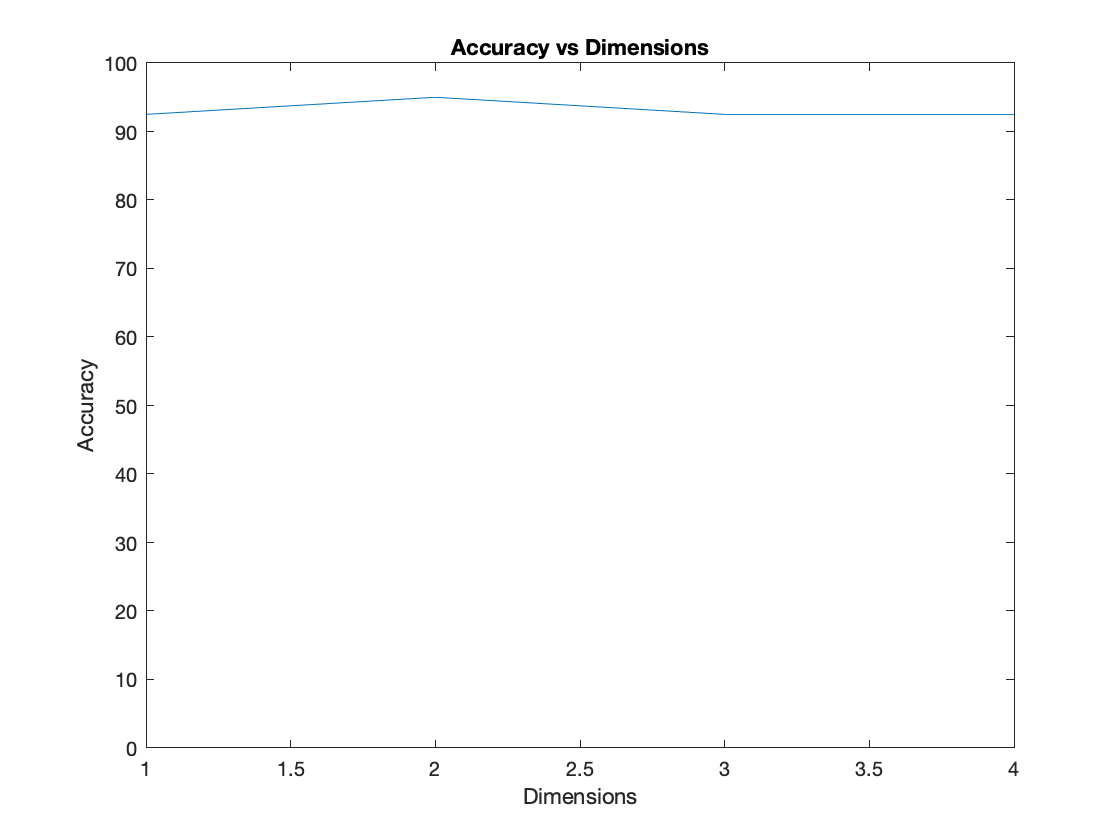

plot(acc)
title("Accuracy vs Dimensions")
xlabel('Dimensions')
ylabel("Accuracy")
ylim([0 100])

**FINAL REPORT**

**Approach (inspired by Matthew’s Lecture):**

We have 40 different classes and we want to learn a projection that separates these classes maximally.

**Sw = “within-class scatter“**

	- Sum of: how much each class deviates from the mean of that class (i.e. sum of the covariances of each class)

	- minimize how far points can stray from the mean

**SB = “between-class scatter” **

	- like a covariance matrix but on the means of each class 

	- mk-m: subtract mean of each class from global mean 

In our new representation of data, we want:

	- classes that are very close to their means (small within-class variance)

	-  high variances between the classes

	- maximize the variance of the class means (distance between means)

…so that they are easily separable.

Therefor, we maximize the ratio of the two by looking for the basis W onto which projections maximize this ratio.

**Results: **

    The abiility of my models to identify the corresponding person in each photograph in the testing set (by determining its LDA projections) is strong (accuracy rates are all above 90%) and the desired goal was achieved. While the accuracies across the different dimensions were high, these accuracies did not correlate with the changes in dimensions (i.e. accuracy stayed consistent as nuber of dimensions increased). 

**NOTES:**

- The suggested functions are just a guide. You can create them or not. Also, you can add or remove input/output parameters as needed.

- Between class scatter:


$$S_B=\sum_{k=1}^K N_k(m_{k}-m)(m_{k}-m)^T$$


                                                                                            *K* is the total number of classes,

                                                                                             $N_k$ is the number of observations on class *k*, 

                                                                                            $m_{k}$is the mean of vectors of class *k* 

                                                                                            $m$ is the mean of all the vectors (global mean).

- Within-class scatter:

 
$$S_w=\sum_{k=1}^K\sum_{i=1}^{N_k}(x_{ik}-m_k)(x_{ik}-m_k)^T$$


                                                                                            where $x_{ik}$ is the $i^{th}$ observation of class *k*.

-      PCA projection is recommended to obtain the features to be used to train the LDA matrix in order to avoid singularity problems. If PCA is not used over the original data, the number of features per observation (10304) will be much larger than the number of observations (360) and the covariance matrices will not have full rank and will not be invertible.